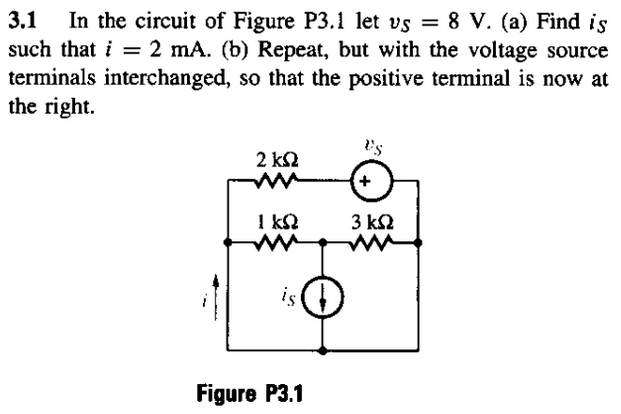

Primero encontramos la tension que cae en la resistencia de 2k, que de acuerdo con la LTK en el lazo en que se encuentran, la tension que entrega la fuente debe completamente consumida por la resistencia de 2k, por lo tanto deben caer los 8V que entrega la fuente. Y sabiendo la tension que cae, podemos calcular la corriente en r2 y aplicar LCK sabiendo que la corriente i=2mA:

clc, clear, close all
format short g

r1 = 2000;
r2 = 1000;
r3 = 3000;
il = 2e-3;
vs = 8;

V_r1 = vs;
i_r1 = V_r1/r1 %corriente en r1 [ohms]

i_r1 =         0.004



i_r2 = i_r1 + il %corriente en r2 [ohms]

i_r2 =         0.006


v_r2 = r2 * i_r2 %tension en r2 [V]

v_r2 =      6


Ahora que sabemos la tension y corriente en r2=1k, sabemos que en el nodo entre r2 y r3, hay 6V por lo que podemos calcular la corriente tambien en r3:

i_r3 = v_r2/r3 %corriente en r3 [A]

i_r3 =         0.002


Sabiendo esta correinte aplicamos de nuevo la LCK, sabemos que ambas corrientes entran al nodo, por lo que la corriente en la fuente de corriente debe ser la suma de i_r2 + i_r3

is = (i_r2+i_r3)*1000 %corriente entregada por la fuiente de corriente [mA]

is =      8


Ahora la verificamos en el simulador

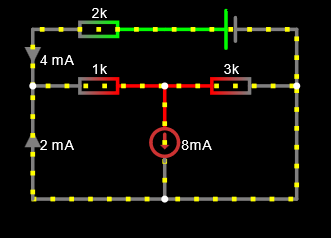

Asi comprobamos que los calculos realizados estan bien hechos.